clear all
clc

% Homework 2 - Problem 1 case x2
% Student Name: Giuditta Sigona
% Created on 16/04/2022
% Last version xx/yy/zz

% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;

%parameters
m1=1000;
m2=10;
k=0.001; %coeff plastica acciaio
B=0.5;

%systems
x1 = (m2*s^2+B*s-k)/((s^2)*(m1*m2*s^2+B*(m1+m2)*s-k*m1));
x2 = (B*s-k)/((s^2)*(m1*m2*s^2+B*(m1+m2)*s-k*m1))

x2 =
 
        0.5 s - 0.001
  -------------------------
  10000 s^4 + 505 s^3 - s^2
 
Continuous-time transfer function.



diff = m2/(m1*m2*s^2+B*(m1+m2)*s-k*m1);

% ************* case x2 *******************

zpk(x2)   % factorized into the zero-pole-gain form

ans =
 
        5e-05 (s-0.002)
  ----------------------------
  s^2 (s+0.05241) (s-0.001908)
 
Continuous-time zero/pole/gain model.




% Sensitivity Bode plot
Cont = pidtune(x2,'pid');

Loop=loopsens(x2,Cont);
Loop.Stable

ans = 0

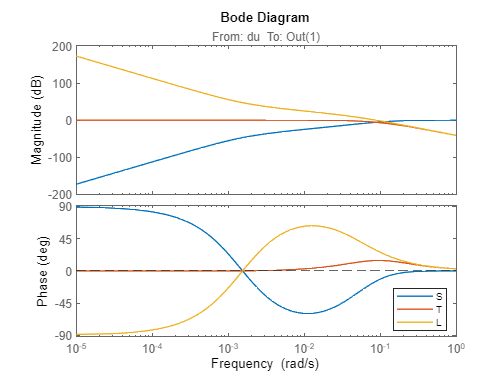

 
figure(1)
bode(Loop.Si,Loop.Ti,Loop.Li)
yline(0,'--')
yline(-180,'--')
legA = legend('S','T','L','Location','SouthEast');
set(legA,'FontSize',8)


% Find alpha
syms a b c d e f g h alpha s

numP =(B*s^4/(m1*m2)-k/(m1*m2));
denP = (s^4+B*(m1+m2)*s^3/(m1*m2)-k*s^2/m2); 
P = numP/denP

$$P = \frac{\frac{s^{4}}{20000}-\frac{1}{10000000}}{s^{4}+\frac{101\,s^{3}}{2000}-\frac{s^{2}}{10000}}$$


numC =(a*s^3 + b*s^2 + c*s + d);
denC = (s^4+e*s^3+f*s^2+g*s+h);
C = numC/denC  % Strictly proper controller m<n

$$C = \frac{a\,s^{3}+b\,s^{2}+c\,s+d}{s^{4}+e\,s^{3}+f\,s^{2}+g\,s+h}$$


p_s= numC*numP + denC*denP

$$p\_s = \left(\frac{s^{4}}{20000}-\frac{1}{10000000}\right)\,\left(a\,s^{3}+b\,s^{2}+c\,s+d\right)+\left(s^{4}+\frac{101\,s^{3}}{2000}-\frac{s^{2}}{10000}\right)\,\left(s^{4}+e\,s^{3}+f\,s^{2}+g\,s+h\right)$$

p_s=vpa(collect(p_s))

$$p\_s = s^{8}+\left(0.00005\,a+e+0.0505\right)\,s^{7}+\left(0.00005\,b+0.0505\,e+f-0.0001\right)\,s^{6}+\left(0.00005\,c-0.0001\,e+0.0505\,f+g\right)\,s^{5}+\left(0.00005\,d-0.0001\,f+0.0505\,g+h\right)\,s^{4}+\left(0.0505\,h-0.0001\,g-0.0000001\,a\right)\,s^{3}+\left(-0.0000001\,b-0.0001\,h\right)\,s^{2}-0.0000001\,c\,s-0.0000001\,d$$


p_star=(s+alpha*(1+j))^4*(s+alpha*(1-j))^4;   % p*(s)
p_star=collect(p_star)

$$p\_star = s^{8}+\left(8\,\alpha \right)\,s^{7}+\left(32\,\alpha^{2}\right)\,s^{6}+\left(80\,\alpha^{3}\right)\,s^{5}+\left(136\,\alpha^{4}\right)\,s^{4}+\left(160\,\alpha^{5}\right)\,s^{3}+\left(128\,\alpha^{6}\right)\,s^{2}+\left(64\,\alpha^{7}\right)\,s+16\,\alpha^{8}$$


eq1=0.00005*a+e+0.0505 == 8*alpha;
eq2=0.00005*b+0.0505*e+f-0.0001 == 32*alpha^2;
eq3=0.00005*c-0.0001*e+0.0505*f+g == 80*alpha^3;
eq4=0.00005*d-0.0001*f+0.0505*g+h == 136*alpha^4;
eq5=0.0505*h-0.0001*g-0.0000001*a == 160*alpha^5;
eq6=-0.0000001*b-0.0001*h == 128*alpha^6;
eq7=-0.0000001*c == 64*alpha^7;
eq8=-0.0000001*d == 16*alpha^8;

sol = solve([eq1, eq2, eq3, eq4, eq5, eq6, eq7, eq8], [a,b,e,f,g,h,c,d]);
a = vpa(sol.a)

$$a = 4055316600.7862238158493090018221\,\alpha^{8}-851290855.90812753063701796401312\,\alpha^{7}+89224629.727349859647018261566782\,\alpha^{6}-1605845127.4655159917728772822524\,\alpha^{5}+68940382.213365804869438253030976\,\alpha^{4}-2128227.1397703188265925449100328\,\alpha^{3}+44612.314863674929823509130783391\,\alpha^{2}-584.51274655159917728772822524064\,\alpha +3.8291501965559539623272504555296$$

b = vpa(sol.b)

$$b = -8029225.637327579958864386411262\,\alpha^{8}+1622126.6403144895263397236007288\,\alpha^{7}-1280170258.1711816255061274035928\,\alpha^{6}+11153.078715918732455877282695848\,\alpha^{5}-136496.83583456885930069456899145\,\alpha^{4}+4055.3166007862238158493090018221\,\alpha^{3}-85.129085590812753063701796401312\,\alpha^{2}+1.1153078715918732455877282695848\,\alpha -0.007306409331894989716096602815508$$

c = vpa(sol.c)

$$c = -640000000.0\,\alpha^{7}$$

d = vpa(sol.d)

$$d = -160000000.0\,\alpha^{8}$$

e = vpa(sol.e)

$$e = -202765.83003931119079246545009111\,\alpha^{8}+42564.542795406376531850898200656\,\alpha^{7}-4461.2314863674929823509130783391\,\alpha^{6}+80292.25637327579958864386411262\,\alpha^{5}-3447.0191106682902434719126515488\,\alpha^{4}+106.41135698851594132962724550164\,\alpha^{3}-2.2306157431837464911754565391696\,\alpha^{2}+8.029225637327579958864386411262\,\alpha -0.050691457509827797698116362522776$$

f = vpa(sol.f)

$$f = 10641.135698851594132962724550164\,\alpha^{8}-2230.6157431837464911754565391696\,\alpha^{7}+64233.805098620639670915091290096\,\alpha^{6}-4055.3166007862238158493090018221\,\alpha^{5}+180.89930688047710026036631735279\,\alpha^{4}-5.5765393579593662279386413479239\,\alpha^{3}+32.116902549310319835457545645048\,\alpha^{2}-0.40553166007862238158493090018221\,\alpha +0.002660283924712898533240681137541$$

g = vpa(sol.g)

$$g = -557.65393579593662279386413479239\,\alpha^{8}+32116.902549310319835457545645048\,\alpha^{7}-3244.2532806289790526794472014577\,\alpha^{6}+212.82271397703188265925449100328\,\alpha^{5}-9.4801169085309225874956902914706\,\alpha^{4}+80.29225637327579958864386411262\,\alpha^{3}-1.6221266403144895263397236007288\,\alpha^{2}+0.021282271397703188265925449100328\,\alpha -0.0001394134839489841556984660336981$$

h = vpa(sol.h)

$$h = 8029.225637327579958864386411262\,\alpha^{8}-1622.1266403144895263397236007288\,\alpha^{7}+170.25817118162550612740359280262\,\alpha^{6}-11.153078715918732455877282695848\,\alpha^{5}+136.49683583456885930069456899145\,\alpha^{4}-4.0553166007862238158493090018221\,\alpha^{3}+0.085129085590812753063701796401312\,\alpha^{2}-0.0011153078715918732455877282695848\,\alpha +0.000007306409331894989716096602815508$$


alpha_A=vpa(solve(a==0,alpha))

$$alpha\_A = \left(\begin{array}{c} 0.016084575569082417513079234415498\\ 0.78730696001887446409890774648628\\ -0.31017512744945531044145507112215+0.63694538363232592511003575523708\,\mathrm{i}\\ -0.31017512744945531044145507112215-0.63694538363232592511003575523708\,\mathrm{i}\\ 0.0017715604429859694139361568157484-0.023029667279837554259007534618077\,\mathrm{i}\\ 0.0017715604429859694139361568157484+0.023029667279837554259007534618077\,\mathrm{i}\\ 0.011667650650857470764910330693358+0.011930024147931522098318725517917\,\mathrm{i}\\ 0.011667650650857470764910330693358-0.011930024147931522098318725517917\,\mathrm{i} \end{array}\right)$$

alpha_B=vpa(solve(b==0,alpha))

$$alpha\_B = \left(\begin{array}{c} -0.012614609810721825207141919377427+0.014379031239782813076247685136414\,\mathrm{i}\\ -0.012614609810721825207141919377427-0.014379031239782813076247685136414\,\mathrm{i}\\ 0.0033389266911975511120806205989448-0.011716939268286701611447660999751\,\mathrm{i}\\ 0.0033389266911975511120806205989448+0.011716939268286701611447660999751\,\mathrm{i}\\ 0.0092799617335082741815970279172485+0.0043555564818878185065776622413208\,\mathrm{i}\\ 0.0092799617335082741815970279172485-0.0043555564818878185065776622413208\,\mathrm{i}\\ 0.10100961198919455361156118992922-12.626500241220267740127258048024\,\mathrm{i}\\ 0.10100961198919455361156118992922+12.626500241220267740127258048024\,\mathrm{i} \end{array}\right)$$

alpha_C=vpa(solve(c==0,alpha))

$$alpha\_C = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

alpha_D=vpa(solve(d==0,alpha))

$$alpha\_D = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

alpha_E=vpa(solve(e==0,alpha))

$$alpha\_E = \left(\begin{array}{c} 0.0063217071182286096890517941696774\\ 0.78737369866383242648250672000246\\ -0.31008300296108348517526295416074-0.6369676776484023596317452548428\,\mathrm{i}\\ -0.31008300296108348517526295416074+0.6369676776484023596317452548428\,\mathrm{i}\\ -0.06061918701970598037066194555744+0.071793118285403596293989601805551\,\mathrm{i}\\ -0.06061918701970598037066194555744-0.071793118285403596293989601805551\,\mathrm{i}\\ 0.078814338528125518003530549469948+0.071576407725078028775775201868204\,\mathrm{i}\\ 0.078814338528125518003530549469948-0.071576407725078028775775201868204\,\mathrm{i} \end{array}\right)$$

alpha_F=vpa(solve(f==0,alpha))

$$alpha\_F = \left(\begin{array}{c} -0.091833803214338329622995132650337+0.10707327824910163885069444006965\,\mathrm{i}\\ -0.091833803214338329622995132650337-0.10707327824910163885069444006965\,\mathrm{i}\\ 0.0063198766332151593603494705403803-0.0065602633396497483782273756663916\,\mathrm{i}\\ 0.0063198766332151593603494705403803+0.0065602633396497483782273756663916\,\mathrm{i}\\ 0.073220705783830926085959079297698+2.4533684971676592691024265098951\,\mathrm{i}\\ 0.073220705783830926085959079297698-2.4533684971676592691024265098951\,\mathrm{i}\\ 0.11710420180115622000235884498984+0.10686490369169411252710204554177\,\mathrm{i}\\ 0.11710420180115622000235884498984-0.10686490369169411252710204554177\,\mathrm{i} \end{array}\right)$$

alpha_G=vpa(solve(g==0,alpha))   %57,5

$$alpha\_G = \left(\begin{array}{c} 0.010639361771702132535253184309974\\ 57.491815278919949917201348798174\\ -0.13605642124637442098953429054343+0.15991865136617914894728659949027\,\mathrm{i}\\ -0.13605642124637442098953429054343-0.15991865136617914894728659949027\,\mathrm{i}\\ 0.0047907667240060192230079975685212-0.011856281347926941756443816153467\,\mathrm{i}\\ 0.0047907667240060192230079975685212+0.011856281347926941756443816153467\,\mathrm{i}\\ 0.17648402183230004429299859416999-0.15983910702626112378238639491828\,\mathrm{i}\\ 0.17648402183230004429299859416999+0.15983910702626112378238639491828\,\mathrm{i} \end{array}\right)$$

alpha_H=vpa(solve(h==0,alpha))

$$alpha\_H = \left(\begin{array}{c} -0.2099303022631627108413514643343+0.25747533119403610872952373345103\,\mathrm{i}\\ -0.2099303022631627108413514643343-0.25747533119403610872952373345103\,\mathrm{i}\\ 0.0030868766553373285151369059829501+0.01706310590102266209377696028175\,\mathrm{i}\\ 0.0030868766553373285151369059829501-0.01706310590102266209377696028175\,\mathrm{i}\\ 0.011780048610107831617786097493733-0.0062948601707989719898689430991429\,\mathrm{i}\\ 0.011780048610107831617786097493733+0.0062948601707989719898689430991429\,\mathrm{i}\\ 0.2960772676008961044065253799256+0.25700904895018673322246071567668\,\mathrm{i}\\ 0.2960772676008961044065253799256-0.25700904895018673322246071567668\,\mathrm{i} \end{array}\right)$$


% pick alpha
s = tf('s');
alpha1 = 57,5;

alpha1 = 57


a1 = eval(subs(a,alpha,alpha1));  % eval convert symbol to value
b1 = eval(subs(b,alpha,alpha1));
c1 = eval(subs(c,alpha,alpha1));
d1 = eval(subs(d,alpha,alpha1));
e1 = eval(subs(e,alpha,alpha1));
f1 = eval(subs(f,alpha,alpha1));
g1 = eval(subs(g,alpha,alpha1));
h1 = eval(subs(h,alpha,alpha1));

C1 =(a1*s^3 + b1*s^2 + c1*s + d1)/(s^4+e1*s^3+f1*s^2+g1*s+h1);
L1=loopsens(x2,C1)

L1 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [8×1 double]
    Stable: 0


poli = L1.Poles

poli = 	1.0e+19 *

   2.2511 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


Stabilita = L1.Stable

Stabilita = 0


% pick alpha
s = tf('s');
alpha2 = 60;

a2 = eval(subs(a,alpha,alpha2));  % eval convert symbol to value
b2 = eval(subs(b,alpha,alpha2));
c2 = eval(subs(c,alpha,alpha2));
d2 = eval(subs(d,alpha,alpha2));
e2 = eval(subs(e,alpha,alpha2));
f2 = eval(subs(f,alpha,alpha2));
g2 = eval(subs(g,alpha,alpha2));
h2 = eval(subs(h,alpha,alpha2));

C2 =(a2*s^3 + b2*s^2 + c2*s + d2)/(s^4+e2*s^3+f2*s^2+g2*s+h2);
L2=loopsens(x2,C2)

L2 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [8×1 double]
    Stable: 0


L2.Stable

ans = 0


% pick alpha
s = tf('s');
alpha3 = 70;

a3 = eval(subs(a,alpha,alpha3));  % eval convert symbol to value
b3 = eval(subs(b,alpha,alpha3));
c3 = eval(subs(c,alpha,alpha3));
d3 = eval(subs(d,alpha,alpha3));
e3 = eval(subs(e,alpha,alpha3));
f3 = eval(subs(f,alpha,alpha3));
g3 = eval(subs(g,alpha,alpha3));
h3 = eval(subs(h,alpha,alpha3));

C3 =(a3*s^3 + b3*s^2 + c3*s + d3)/(s^4+e3*s^3+f3*s^2+g3*s+h3);
L3=loopsens(x2,C3)

L3 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [8×1 double]
    Stable: 0


L3.Stable

ans = 0

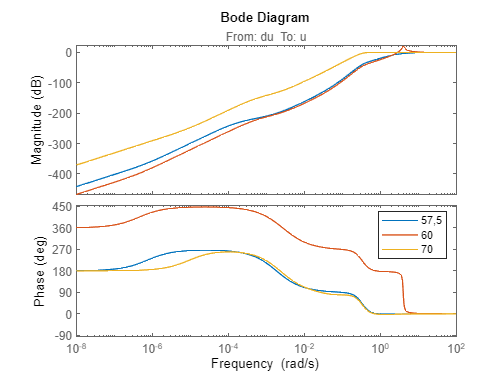



figure(2)
bode(L1.Si,L2.Si, L3.Si)
legend('57,5','60', '70')

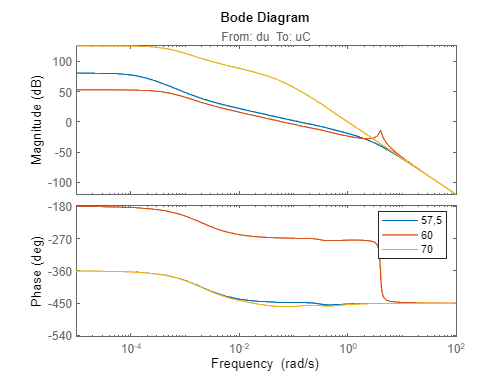

bode(L1.Ti,L2.Ti, L3.Ti)
legend('57,5','60', '70')

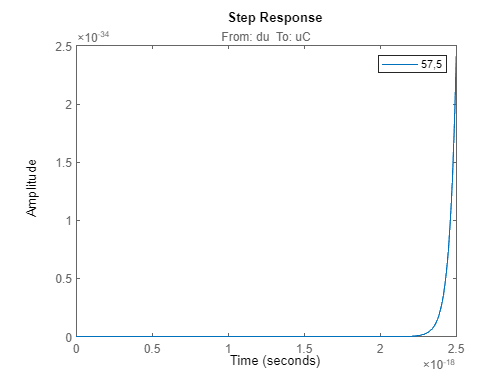


figure(3)
step(L1.Ti)
yline(1,'--')
legend('57,5')

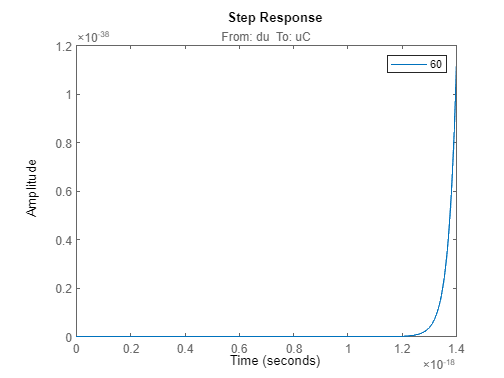


step(L2.Ti)
yline(1,'--')
legend('60')

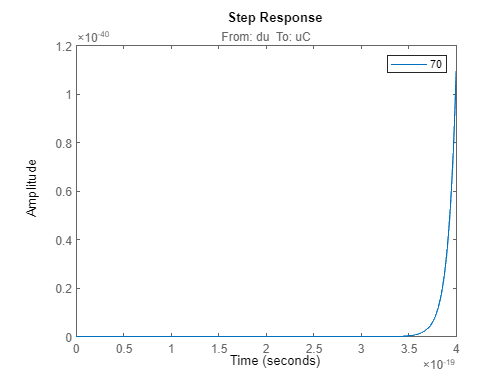


step(L3.Ti)
yline(1,'--')
legend('70')